Assignment 1

rng(10)
A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

eigs = roots(A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


%% System Parameters
N = 10000;  % Number of time steps
sigma_e = 0.1;  % Standard deviation of process noise
% sigma_e = 0

k = 1;  % Input delay
alpha = 0.5

alpha = 0.5000



% Initialize
G = [];
S = [B, zeros(length(A)-length(B))]; % Pad B with zeros to make S as long as A



m = 5

m = 5


for i = 1:m
    % Augment with first element of S
    G = [G, S(1)];

    % Update S
    S = [S(2:end) - S(1) *A(2:end), 0] ;
end



% Remove last element
S = S ( 1 : end-1)

S =     0.1382   -0.3724    0.3322   -0.0980


G

G =     0.4453    0.0172    0.0503    0.0815    0.1107


R = conv(B,G)

R =     0.1983   -0.7543    1.1055   -0.7384    0.1900   -0.0616    0.1635   -0.1485    0.0454



% Setpoint (constant or step change)
omega = 2000*sum(S) * ones(N, 1);  % Constant reference setpoint
% omega = 1*ones(N,1);
% omega = 1/S(1) * square(2*pi*1/50*(1:1:N),50)

% Initialize variables
y = zeros(N, 1);  % System output
u = zeros(N, 1);  % Control input
e = sigma_e * randn(N, 1);  % Process noise (Gaussian)


%% Closed-loop Simulation
for t = max([length(A), length(B),length(R)])+1:N
    % Collect past values safely
    y_past = y(t-1:-1:t-length(A)+1);
    u_past = u(t-k:-1:t-k-length(B)+1);

    % Compute system output
    y(t) = -A(2:end) * y_past + B * u_past + e(t);
    
    % Compute control input using the P-controller
    % u(t) = alpha * (omega(t) - y(t));
    
    % MVC0
    u(t) = 1/(R(1)) * (omega(t)-S*y(t:-1:t-length(S)+1) - R(2:end)*u(t-1:-1:t-length(R)+1));
end
disp("y_mean  = " + mean(y(end/2:end)))

y_mean  = 1838.8618


disp("u_mean  = " + mean(u(end/2:end)))

u_mean  = 226.6102


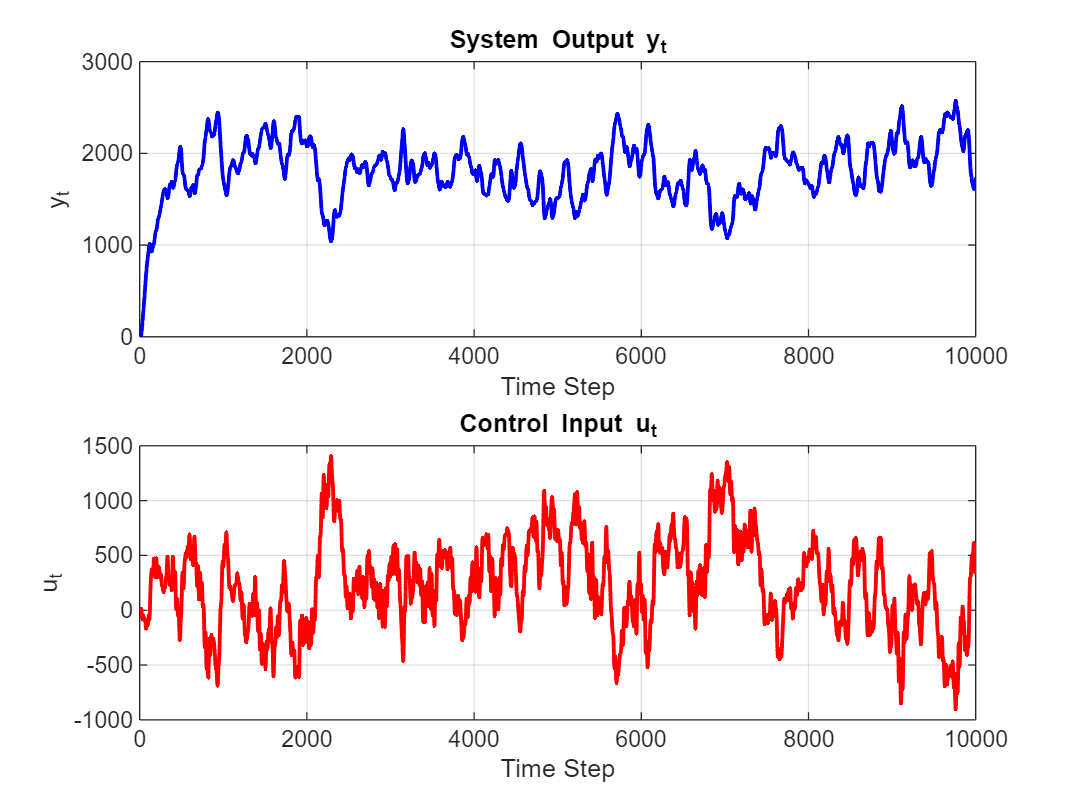


%% Plot Results
figure;
subplot(2,1,1);
plot(y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;

subplot(2,1,2);
plot(u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

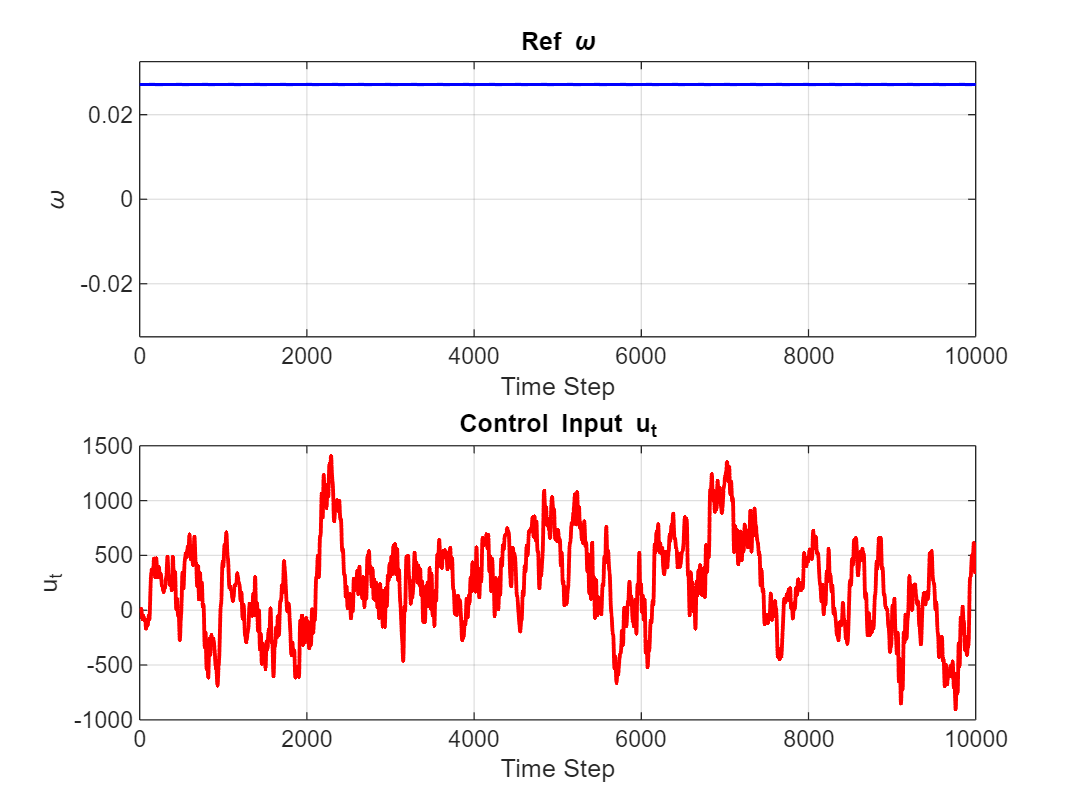


figure
subplot(2,1,1)
plot(omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,1,2)
plot(u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;